# Entregable 2

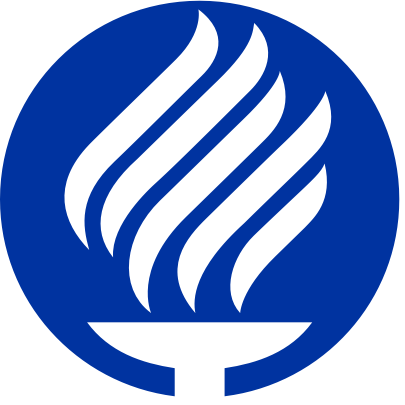

#### Tecnologico de Monterrey Campus Guadalajara 

#### Modelación computacional de sistemas eléctricos (Gpo 213)

**Juan Daniel Muñoz Dueñas**

**Hugo Alejandro Gómez Herrera **

**Iker Ochoa Villaseñor **

**Oliver Josel Hernández Rebollar**

Inicializar

clearvars
close all
clc

Placa Positiva

v = 5;

dx = -20;

height = 5;
anchor = 6;

graphLimit = 50;

verticesR = [   -v ,-v, -v; % Vertice 1
                v, -v, -v;  % Vertice 2
                v, v, -v;   % Vertice 3
                -v, v, -v;  % Vertice 4
                -v, -v, v;  % Vertice 5
                v, -v, v;   % Vertice 6
                v, v, v;    % Vertice 7
                -v, v, v] .* [0.5 , height, anchor] + [dx, 0 ,0]; % Vertice 8

carasR = [1 2 6 5;  % Cara 1
          2 3 7 6;  % Cara 2
          3 4 8 7;  % Cara 3
          4 8 5 1;  % Cara 4
          5 6 7 8;  % Cara 5
          1 2 3 4]; % Cara 6


Placa negativa

verticesB = [   -v ,-v, -v; % Vertice 1
                v, -v, -v;  % Vertice 2
                v, v, -v;   % Vertice 3
                -v, v, -v;  % Vertice 4
                -v, -v, v;  % Vertice 5
                v, -v, v;   % Vertice 6
                v, v, v;    % Vertice 7
                -v, v, v] .* [0.5 , height, anchor] - [dx, 0 ,0]; % Vertice 8

carasB = [1 2 6 5;  % Cara 1
          2 3 7 6;  % Cara 2
          3 4 8 7;  % Cara 3
          4 8 5 1;  % Cara 4
          5 6 7 8;  % Cara 5
          1 2 3 4]; % Cara 6

sizePlane = 50;
paso = 10;

x0 = -sizePlane;
x1 = sizePlane;
y0 = -sizePlane;
y1 = sizePlane;
z0 = -sizePlane;
z1 = sizePlane;

[xGrid, yGrid, zGrid] = meshgrid(x0:paso:x1,y0:paso:y1,z0:paso:z1);

Se colocan los puntos de carga en las placas, se calcula el campo magnetico y se grafica con la función quiver:

k = 8.99*10^9;
Cd = 1;
Qp = 20; % Coulomb
Qn = -20; % Coulomb

Rxn = xGrid + dx; % Obtenemos todos los puntos en X
Ryn = yGrid ; % Obtenemos todos los puntos en Y
Rzn = zGrid + (v * height) ; % Obtenemos todos los puntos en Z

Rxp = xGrid - dx; % Obtenemos todos los puntos en X
Ryp = yGrid ; % Obtenemos todos los puntos en Y
Rzp = zGrid + (v * height) ; % Obtenemos todos los puntos en Z

Rn = sqrt(Rxn.^2 + Ryn.^2 + Rzn.^2).^2;
Rp = sqrt(Rxp.^2 + Ryp.^2 + Rzp.^2).^2;

Ex = k .* Qn .* Rxn ./ Rn; % Se calcula el campo magnetico en cada punto en X
Ey = k .* Qn .* Ryn ./ Rn; % Se calcula el campo magnetico en cada punto en Y
Ez = k .* Qn .* Rzn ./ Rn; % Se calcula el campo magnetico en cada punto en Z

Ex = Ex + k .* Qp .* Rxp ./ Rp; % Se calcula el campo magnetico en cada punto en X
Ey = Ey + k .* Qp .* Ryp ./ Rp; % Se calcula el campo magnetico en cada punto en Y
Ez = Ez + k .* Qp .* Rzp ./ Rp; % Se calcula el campo magnetico en cada punto en Y

E = sqrt((Ex).^2 + (Ey).^2 + (Ez).^2);

i = (Ex) ./ E;
j = (Ey) ./ E;
k = (Ez) ./ E;

h = quiver3(xGrid, yGrid, zGrid, i, j, k);

Graficacion 

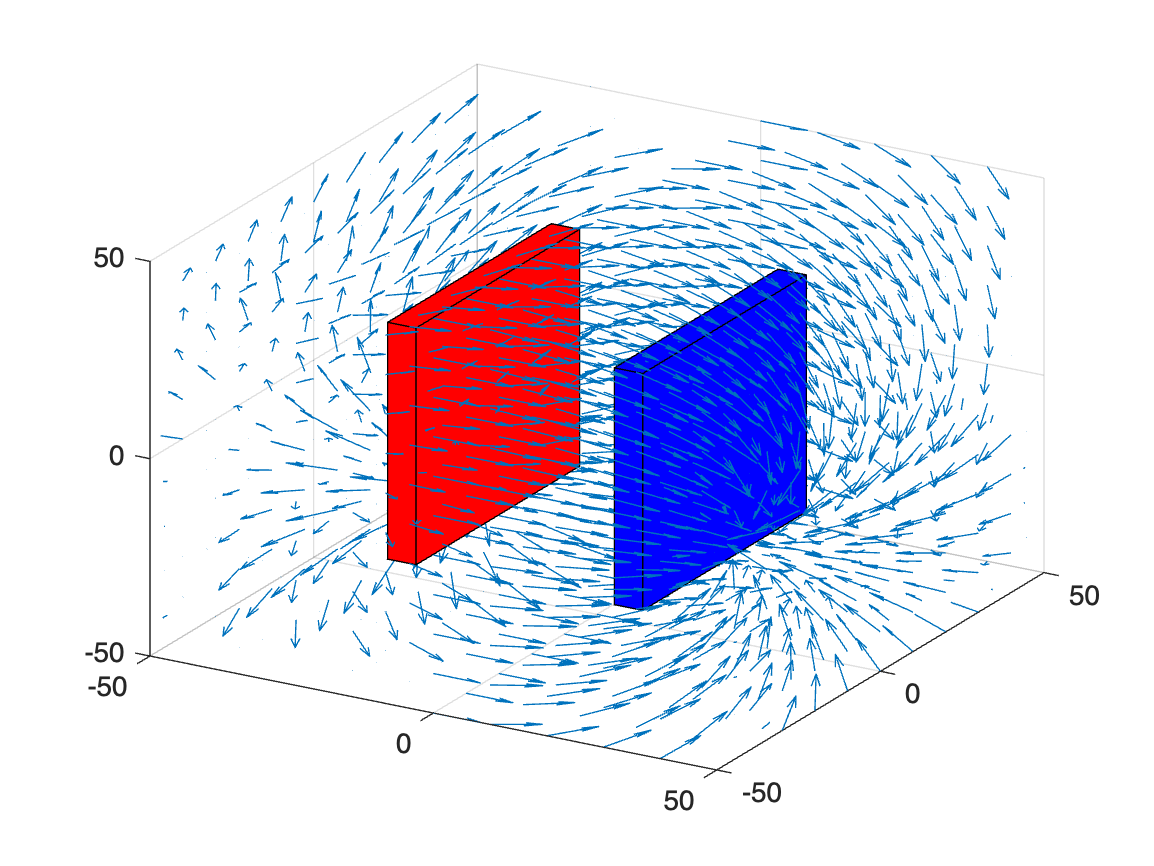

patch('Faces',carasR,'Vertices',verticesR,'FaceColor','r');
patch('Faces',carasB,'Vertices',verticesB,'FaceColor','b');
view(30,30)
axis([-graphLimit,graphLimit,-graphLimit,graphLimit,-graphLimit,graphLimit])
grid on 